N = 2048; % Size of the IFFT block available at Tx
M = 64; % Order of QAM modulation being used at the Tx...
k = log2(M); % The number of bits each symbol will represent...
codeRate = 0.5; % The code-rate being used by the convolutional encoder at the Tx...
lenData = (N-2)*(1/2)*(k)*(codeRate); % The amount (or length) of the data we should generate...

data = randi([1], lenData, 1) % Our data bit stream

data =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


## Encoder

txTrellis = poly2trellis(7, [171 133]);
traceBackLength = 34;
encodedData = convenc(data, txTrellis);

## Modulation and Impose Hermitian Symmetry:

modulatedData = qammod(encodedData, M, "InputType", "bit", "UnitAveragePower", true);
augmentedModulatedData = [0; modulatedData(1:end); 0; conj(modulatedData(end:-1:1))];
Ftx = augmentedModulatedData;

## Define Channel and Add CP

h = [0.9; 0.2; 0.4]; % Channel coefficients...

% The length of the cyclic prefix required is related to the 
% length of the channel...
cpLen = 3*length(h) + 1;

## IFFT

ifftOp = ifft(augmentedModulatedData);

## Create OFDM symbol

ofdmSymbol = [ifftOp(end-cpLen+1:end); ifftOp];

## Pass over the Channel

y = conv(h, ofdmSymbol) % Using the convolutional function in MatLab...

y =    -0.0012
   -0.0306
   -0.0085
   -0.0525
   -0.0104
   -0.0714
   -0.0138
   -0.1134
   -0.0216
   -0.3060


y = awgn(y, 30, 'measured'); % Adding White Gaussian Noise...

## Define Attributes of the target:

c = 3e8; % The speed of light
targetRCSdBm = 20; % A possible RCS value for a ground vehicle...
targetRCS = 10^(targetRCSdBm/10); % The RCS value in square metres (that is what 'sm' stands for in dBsm)...
d = 10; % The distance to the target in metres...
fC = 5.5e9; % The frequency of the central subcarrier...

%b = sqrt((c*targetRCS)/((4*pi)^3*(d)^4*(fC)^2)); % The attenuation when the EM wave hits the target...
b = 1;

## Emulate the Reflection

% Let's initially assume that the target is at rest...
r = b*y

r =    -0.0011
   -0.0313
   -0.0077
   -0.0528
   -0.0108
   -0.0721
   -0.0138
   -0.1135
   -0.0218
   -0.3064


r2 = conv(h, r)

r2 =    -0.0010
   -0.0284
   -0.0136
   -0.0616
   -0.0233
   -0.0882
   -0.0311
   -0.1338
   -0.0478
   -0.3255


r2 = awgn(r2, 30, 'measured'); % Adding White Gaussian Noise...

## At the Rx remove CP

r2 = r2(cpLen+1:end);
r2 = r2(1:end-2*(length(h) - 1));
fftChannel = fft([h; zeros(N-length(h), 1)]);
Frx = fft(r2);
Frx = Frx./fftChannel;

## Divide Rx Frame by Tx one

F = Frx./Ftx; % Dividing the received frame by the one that was sent...

## FFT of each Row

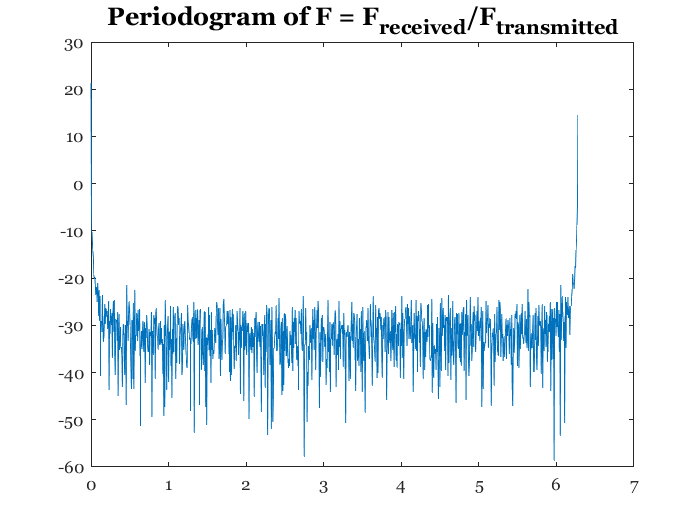

Fdata = F(2:1024);
[pxx, w] = periodogram(Fdata);
plot(w, 10*log10(pxx));
title('\bf\fontname{Georgia}\fontsize{15}Periodogram of F = F_{received}/F_{transmitted}');
set(gca,'Fontname', 'Georgia');

## Second plot

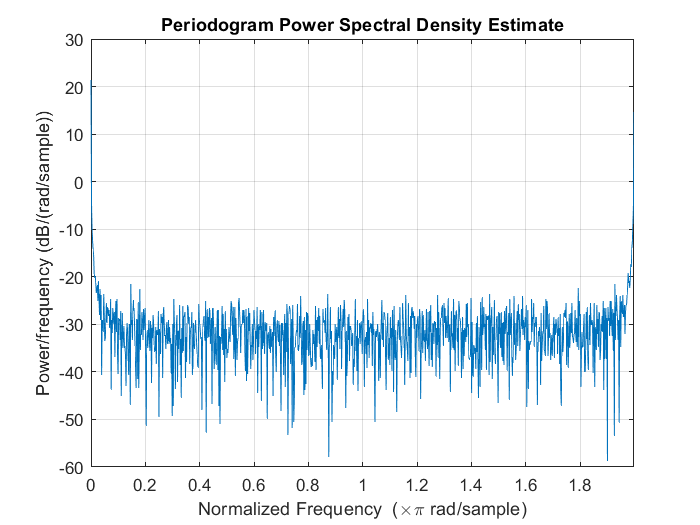

periodogram(Fdata)